% Name: Mukesh Aryal
% Student No: 268456
% E03

k=1.4, t=sqrt(1-(1/k^2));

k = 1.4000

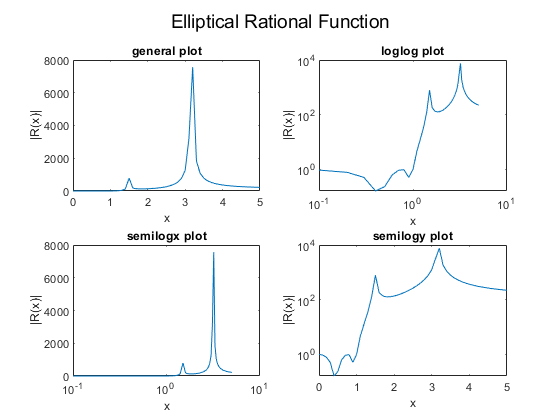

R=@(x) ((1+t)*(1+sqrt(t))^2.*x.^4-2*(1+t)*(1+sqrt(t))*x.^2+ones(size(x)))...
    ./((1+t)*(1-sqrt(t))^2.*x.^4-2*(1+t)*(1-sqrt(t)).*x.^2+ones(size(x)));

x=0:0.1:5;
y=abs(R(x));
subplot(221), plot(x,y); xlabel('x'), ylabel('|R(x)|'), title('general plot')
subplot(222), loglog(x,y); xlabel('x'), ylabel('|R(x)|'), title('loglog plot')
subplot(223), semilogx(x,y); xlabel('x'), ylabel('|R(x)|'), title('semilogx plot')
subplot(224), semilogy(x,y); xlabel('x'), ylabel('|R(x)|'), title('semilogy plot')
suptitle('Elliptical Rational Function');